clear
clc

syms theta omega_s l l_1 l_2 l_3 w_1 w_2 h_1 h_2 h_3 a_1 a_2 a_3 d theta_1 theta_2 theta_3 theta_4 theta_5 theta_6

robot = rigidBodyTree;

%-------------- Variables-----------%
M{1} = [1 0 0 0;
        0 1 0 0;
        0 0 1 .147;
        0 0 0 1];
M{2} = [1 0 0 0;
        0 0 -1 -.147;
        0 1 0 .147;
        0 0 0 1];
M{3} = [1 0 0 0;
        0 0 -1 -.147;
        0 1 0 .574;
        0 0 0 1];
M{4} = [1 0 0 0;
        0 0 1 -.025;
        0 -1 0 .931;
        0 0 0 1];
M{5} = [1 0 0 0;
        0 -1 0 -.141;
        0 0 -1 .931;
        0 0 0 1];
M{6} = [1 0 0 0;
        0 0 1 -.141;
        0 -1 0 1.047;
        0 0 0 1];


%---------- Joint Table--------------%
jointTab{1}.w = [0; 0; 1];
jointTab{1}.q = [0; 0; .147];
jointTab{1}.v = cross(-jointTab{1}.w,jointTab{1}.q);
jointTab{1}.jType = 'revolute';
jointTab{1}.ang = theta_1;

jointTab{2}.w = [0; 1; 0];
jointTab{2}.q = [0; -.147; .147];
jointTab{2}.v = cross(-jointTab{2}.w,jointTab{2}.q);
jointTab{2}.jType = 'revolute';
jointTab{2}.ang = theta_2;

jointTab{3}.w = [0; 1; 0];
jointTab{3}.q = [0; -.147; .574];
jointTab{3}.v = cross(-jointTab{3}.w,jointTab{3}.q);
jointTab{3}.jType = 'revolute';
jointTab{3}.ang = theta_3;

jointTab{4}.w = [0; -1; 0];
jointTab{4}.q = [0; -.025; .611];
jointTab{4}.v = cross(-1*(jointTab{4}.w),jointTab{4}.q);
jointTab{4}.jType = 'revolute';
jointTab{4}.ang = theta_4;

jointTab{5}.w = [0; 0; -1];
jointTab{5}.q = [0; -.141; .611];
jointTab{5}.v = cross(-1*(jointTab{5}.w),jointTab{5}.q);
jointTab{5}.jType = 'revolute';
jointTab{5}.ang = theta_5;

jointTab{6}.w = [0; 0; -1];
jointTab{6}.q = [0; -.141; .727];
jointTab{6}.v = cross(-1*(jointTab{6}.w),jointTab{6}.q);
jointTab{6}.jType = 'revolute';
jointTab{6}.ang = theta_6;

%%%%%%%%%%%%%%%%%%%%%%% Forward Kinematics %%%%%%%%%%%%%%%%%%%%%%%%

T = FwdKin(jointTab, M);

T_doub = homePos(T);

T_relativePrev = relPrev(T_doub);

%%%%%%%%%%%%%%%%%%%%%%%%%% Robot Assembly %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

assem = robo(jointTab, T_relativePrev, robot); % Used to "assemble" the robot.
config = homeConfiguration(robot);

% showdetails(robot) 

--------------------
Robot: (6 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        body1        joint1      revolute             base(0)   body2(2)  
   2        body2        joint2      revolute            body1(1)   body3(3)  
   3        body3        joint3      revolute            body2(2)   body4(4)  
   4        body4        joint4      revolute            body3(3)   body5(5)  
   5        body5        joint5      revolute            body4(4)   body6(6)  
   6        body6        joint6      revolute            body5(5)   
--------------------


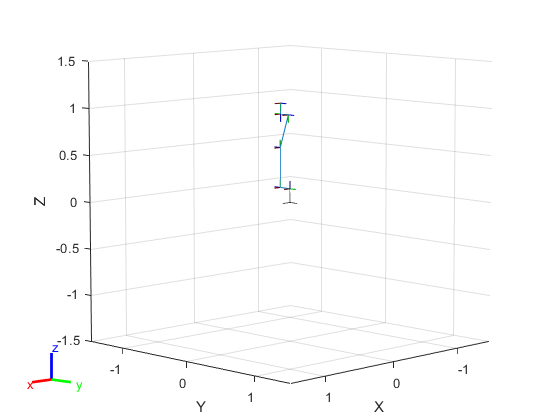


show(robot); 

function assem = robo(jointTab, T, robot)

    % Loop to create Joints and Bodies. Loops based on the number of Joints
    % of the Joint Table (jointTab).
    for i = 1:length(jointTab)
        
        body{i} = rigidBody(append('body',int2str(i)));
        
        joint{i} = rigidBodyJoint(append('joint',int2str(i)),jointTab{1}.jType);
        
    end
    
    % Sets transformation to each body based on the Transformations
    % previously calculated. Joins the joint to the body, and adds it to
    % the RobotTree (Established outside function).
    for j = 1:length(body)
        
        setFixedTransform(joint{j},T{j});
        
        body{j}.Joint = joint{j};
        
        if j == 1
            addBody(robot,body{1},'base');
        else
            addBody(robot,body{j},body{j-1}.Name);     
        end    
    end
    
    assem = true;

end

function T = FwdKin(jointTab, M)

    for i = 1:length(jointTab)
        
        ang = jointTab{i}.ang;
        
        omega_s = [0 -jointTab{i}.w(3) jointTab{i}.w(2);
                   jointTab{i}.w(3) 0 -jointTab{i}.w(1);
                   -jointTab{i}.w(2) jointTab{i}.w(1) 0];
        
        pos = (eye(3)*ang + (1-cos(ang))*omega_s + (ang - sin(ang))*omega_s^2)*jointTab{i}.v;
        rotMat = eye(3) + (sin(ang)*omega_s) + ((1 - cos(ang))*(omega_s^2));
        
        if i == 1
            es{i} = [[rotMat; 0 0 0] , [pos; 1]];   
        else
            es{i} = es{i-1}*([[rotMat; 0 0 0] , [pos; 1]]);
        end
        T{i} = simplify(es{i}*M{i});
        
    end

end

function J = autoJacob(jointTab, T)

    for j = 1:(length(T)-1)
        
        if srtcmp(jointTab{j}.jType, 'revolute')
            
            jv = simplify(diff(T{length(T)}(1:3,4),jointTab{j}.ang));

            jw = T{j}(1:3,3);
            
        elseif strcmp(jointTab{j}.jType, 'prismatic')
            
            jv = simplify(diff(T{length(T)}(1:3,4),jointTab{j}.ang));
            
            jw = [0;0;0];
    
        end
        
        if j == 1
            J = [[jv;jw]];
        else
            J = [J,[jv;jw]];
        end    
    end
    
    J = simplify(J);
end

function T_doub = homePos(T)

theta_1 = 0;
theta_2 = 0;
theta_3 = 0;
theta_4 = 0;
theta_5 = 0;
theta_6 = 0;

    for i = 1:length(T)
        T_doub{i} = double(subs(T{i})); 
    end
end

function T_relativePrev = relPrev(T_doub)
    for i = 1:length(T_doub)
        if i == 1
            T_relativePrev{i} = T_doub{i};
        else 
            T_relativePrev{i} = [[inv(T_doub{i-1}(1:3,1:3))*T_doub{i}(1:3,1:3); 0 0 0], [inv(T_doub{i-1}(1:3,1:3))*(T_doub{i}(1:3,4)-T_doub{i-1}(1:3,4)); 1]];
        end
    end
end